clc, clear, close all
format short g

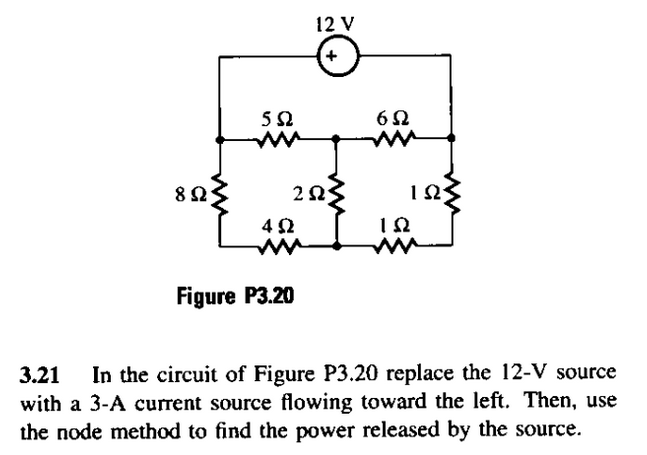

De acuerdo con el enunciado redibujamos el circuito y vemos que podemos reducir el circuito sumando las resistencias en serie

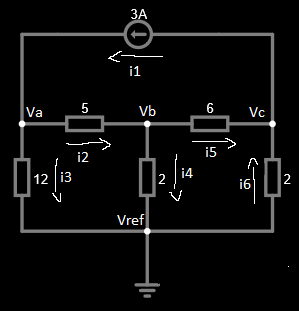

Definimos las corrientes para cada nodo

syms Va Vb Vc
Vref = 0;

i1 = 3;
i2 = (Va-Vb)/5;
i3 = (Va-Vref)/12;
i4 = (Vb-Vref)/2;
i5 = (Vb-Vc)/6;
i6 = (Vref-Vc)/2;


Ahora las ecuaciones de nodo

nodo_a = simplify(3-((Va-Vb)/5)-((Va-Vref)/12)==0)

$$nodo\_a = 17\,\mathrm{Va}=12\,\mathrm{Vb}+180$$

nodo_b = simplify(((Va-Vb)/5)-((Vb-Vref)/2)-((Vb-Vc)/6)==0)

$$nodo\_b = 6\,\mathrm{Va}+5\,\mathrm{Vc}=26\,\mathrm{Vb}$$

nodo_c = simplify(((Vb-Vc)/6)+((Vref-Vc)/2)-(3)==0)

$$nodo\_c = \mathrm{Vb}=4\,\mathrm{Vc}+18$$

ya con las ecuaciones resolvemos el sistema 3x3 para encontrar las tensiones de nodo:

m = [17 -12 0;6 -26 5;0 1 -4];
n = [180;0;18];
h = m\n;

Va = h(1,1) %[V]

Va =     12


Vb = h(2,1) %[V]

Vb =      2


Vc = h(3,1) %[V]

Vc =     -4


Ahora que tenemos las tensiones de nodo podemos calcular la potencia entregada por la fuente de corriente:

pf = (abs(Va)+abs(Vc))*i1 %[W]

pf =     48


Por ultimo queda verificar en el simulador: